# FRA231: Robot Modelling & Experimentation (RMX)

โดย อาจารย์ ธนัชชา ชูพจน์เจริญ

## การบ้านที่ 1

ในพื้นที่การแข่งขันหุ่นยนต์ สนามประลองถูกแบ่งออกเป็นช่องตารางสี่เหลี่ยมจัตุรัส โดยที่พิกัดของตำแหน่งสามารถระบุได้ด้วยจำนวนเต็ม (ทั้งบวก ลบ และ ศูนย์) ยกตัวอย่างเช่น


$$\mathbf{p}=\left\lbrack \begin{array}{c}
-2\\
1
\end{array}\right\rbrack$$


กำหนดให้คำสั่งของหุ่นยนต์สามารถเขียนได้ดังต่อไปนี้

- $0\Rightarrow$ อยู่กับที่

- $1\Rightarrow$เคลื่อนที่ไปข้างหน้า 1 ช่อง

- $2\Rightarrow$หันซ้าย 90 องศา

- $3\Rightarrow$หันขวา 90 องศา

- $4\Rightarrow$ถอยหลัง 1 ช่อง

จงเขียน function trackBot() ที่รับตัวแปร

- ${\mathbf{p}}_i$ : เวกเตอร์ ขนาด $2$ ที่ระบุตำแหน่งของช่องเริ่มต้น (จำนวนเต็มเท่านั้น)

- $\mathbf{c}$ : array ของ คำสั่งที่ประกอบด้วย 0,1,2,3,หรือ 4 เท่านั้น (array ของ char)

- $\mathbf{W}:$ เมตริกซ์ ขนาด $\left(2\times \textrm{จำนวนช่องที่มีกำแพง}\right)$ ที่ระบุถึงตำแหน่งของช่องที่มีกำแพง (จำนวนเต็มเท่านั้น) หากไม่ระบุ $\mathbf{W}$ ถือว่าไม่มีกำแพง 

trackBot() จะมีพฤติกรรมดังต่อไปนี้

- ให้หุ่นยนต์เริ่มจากหันหน้าไปทางทิศเหนือเสมอ (ยกตัวอย่างดังภาพ)

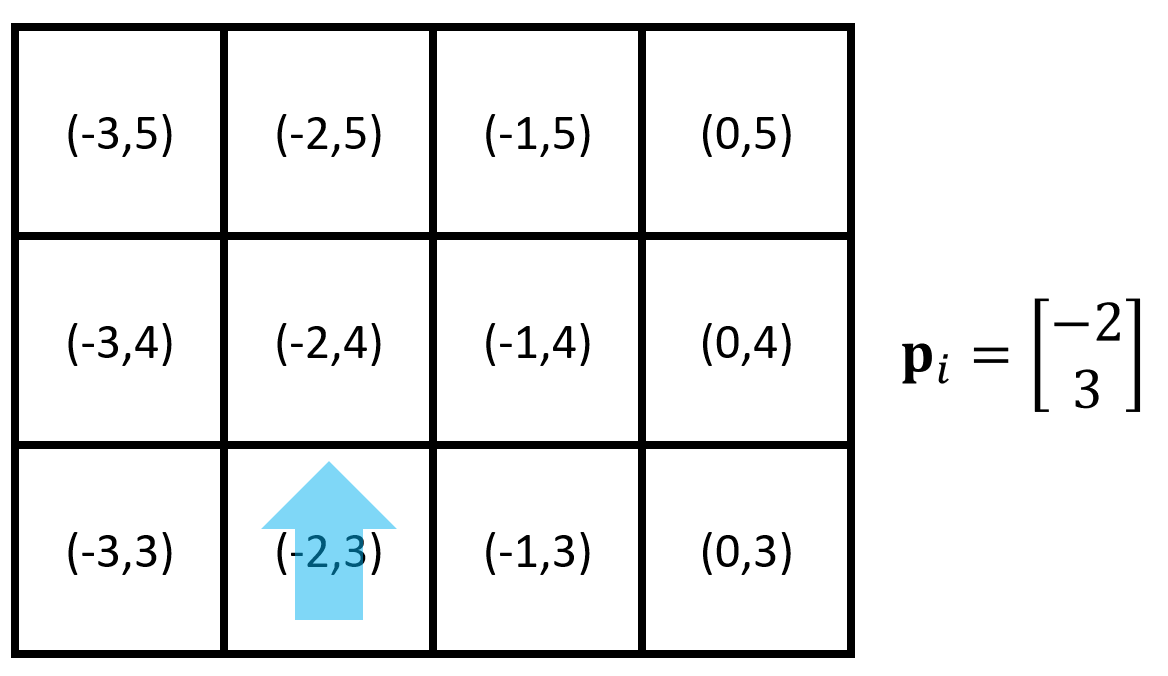

- หากไม่มีข้อผิดพลาดในการใส่ input argument $\textrm{flag}=1$ 

- หากไม่มีข้อผิดพลาดใดๆ ${\mathbf{p}}_f$เป็นตำแหน่งของช่องสุดท้ายที่หุ่นยนต์เคลื่อนที่ไปถึง\

- หากไม่มีข้อผิดพลาดใดๆ $\mathbf{P}$ จะเป็นเมตริกซ์ ขนาด $\left(2\times \textrm{จำนวนช่องในเส้นทางทั้งหมด}\right)$ ที่ระบุถึงช่องที่หุ่นยนต์ได้เดินผ่าน โดยที่จะไม่มีช่องเดียวกันอยู่ติดในกันในเส้นทาง ซึ่งเขียนเป็นความสัมพันธ์ได้ดังต่อไปนี้


$$\begin{array}{l}
\mathbf{P}=\left\lbrack \begin{array}{cccc}
{\mathbf{p}}_1  & {\mathbf{p}}_2  & \cdots  & {\mathbf{p}}_N 
\end{array}\right\rbrack \\
{\mathbf{p}}_1 ={\mathbf{p}}_i \\
{\mathbf{p}}_N ={\mathbf{p}}_f \\
{\mathbf{p}}_{k+1} \not= {\mathbf{p}}_k \;\forall k=1,\cdots ,N-1
\end{array}$$


$\textrm{flag}=-1#$ ถ้าเกิดความผิดพลาดในการระบุ input ${\mathbf{p}}_i$

- $\textrm{flag}=-11$ ถ้า ${\mathbf{p}}_i$ มีขนาดไม่ถูกต้อง

- $\textrm{flag}=-12$ ถ้า ${\mathbf{p}}_i$ มีสมาชิกที่ไม่ใช่จำนวนเต็ม

$\textrm{flag}=-2#$ ถ้าเกิดความผิดพลาดในการระบุ input $\mathbf{c}$

- $\textrm{flag}=-21$ ถ้า $\mathbf{c}$ ไม่ใช่ array ของ char

- $\textrm{flag}=-22$ ถ้า $\mathbf{c}$ มีสมาชิกที่ไม่ใช่ 0, 1, 2, 3, หรือ 4

$\textrm{flag}=-3#$ ถ้าเกิดความผิดพลาดในการระบุ input $\mathbf{W}$

- $\textrm{flag}=-31$ ถ้า $\mathbf{W}$มีขนาดไม่ถูกต้อง

- $\textrm{flag}=-32$ ถ้า $\mathbf{W}$ มีสมาชิกที่ไม่ใช่จำนวนเต็ม

$\textrm{flag}=-4$ ถ้าจุดเริ่มต้นอยู่ในกำแพง

%  [P,p_f,flag] = trackBot(p_i,c,W)
%  [P,p_f,flag] = trackBot(p_i,c)